# Digits Prediction - Data Mining 

In this project we're going to use data to train an algorithm to predict the handwriting digits.

First we determine the address of our dataset

filenameImagesTrain = "D:\Teachers\DR  M. Rostaee\Matlab Workshop\Exercises\Project - Seyedali Shohadaalhosseini\MNIST Digit prediction Project\data\train-images-idx3-ubyte.gz";
filenameLabelsTrain = 'D:\Teachers\DR  M. Rostaee\Matlab Workshop\Exercises\Project - Seyedali Shohadaalhosseini\MNIST Digit prediction Project\data\train-labels-idx1-ubyte.gz';
filenameImagesTest = 'D:\Teachers\DR  M. Rostaee\Matlab Workshop\Exercises\Project - Seyedali Shohadaalhosseini\MNIST Digit prediction Project\data\t10k-images-idx3-ubyte.gz';
filenameLabelsTest = 'D:\Teachers\DR  M. Rostaee\Matlab Workshop\Exercises\Project - Seyedali Shohadaalhosseini\MNIST Digit prediction Project\data\t10k-labels-idx1-ubyte.gz';
% XTrain = processImagesMNIST(filenameImagesTrain);
% YTrain = processLabelsMNIST(filenameLabelsTrain);
% XTest = processImagesMNIST(filenameImagesTest);
% YTest = processLabelsMNIST(filenameLabelsTest);

Let's check the 10th Value of XTrain and Its YTrain

size(XTrain)

ans =           28          28           1       60000


x10th = XTrain(:, :, 1, 10)

x10th =   28(S) × 28(S) × 1(C) × 1(B) dlarray

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0      

y10th = YTrain(10)

y10th = categorical
     4 


We convert these values to matrix to show

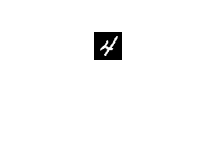

x10th = extractdata(x10th);
figure(1);
imshow(x10th);

y10th

y10th = categorical
     4 


Let's show a couple

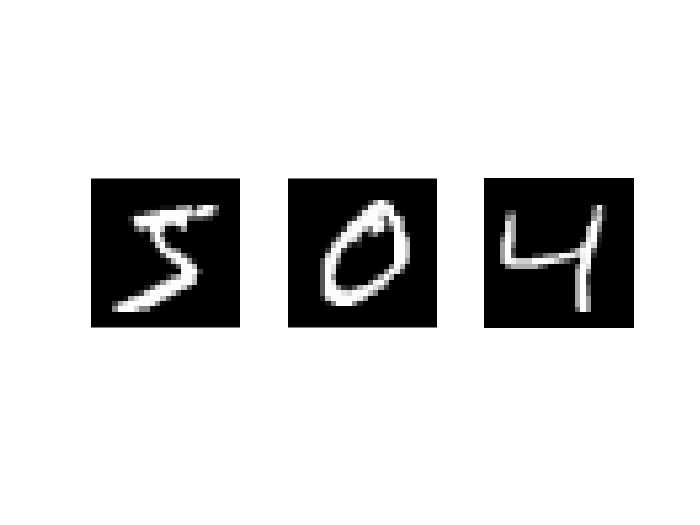

figure(2);

subplot(1, 3, 1);
data_dlarray = XTrain(:, :, 1, 1);
extractedData = extractdata(data_dlarray);
imshow(extractedData);

subplot(1, 3, 2);
data_dlarray = XTrain(:, :, 1, 2);
extractedData = extractdata(data_dlarray);
imshow(extractedData);

subplot(1, 3, 3);
data_dlarray = XTrain(:, :, 1, 3);
extractedData = extractdata(data_dlarray);
imshow(extractedData);

YTrain(1)

ans = categorical
     5 


YTrain(2)

ans = categorical
     0 


YTrain(3)

ans = categorical
     4 


XTrain_Matrix = extractdata(XTrain);
class(XTrain_Matrix)

ans = 'double'

Reshaped_Matrix = reshape(XTrain_Matrix, [60000, 28*28*1])

Reshaped_Matrix =          0         0         0         0         0         0         0         0         0         0         0         0    0.5176         0         0         0    0.7451         0    0.9490         0    0.5804         0         0         0         0         0         0         0         0         0         0    0.9922         0    0.9922         0         0         0         0         0    0.9961         0         0         0         0    0.9922         0    0.9922         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.9961         0    0.2902         0    0.9922         0         0         0         0         0         0         0         0         0         0    0.6078         0    1.0000         0         0         0         0         0    0.9961         0         0         0         0    0.9882         0    0.9922         0 

Adding YTrain(Category) as a column to the end of the dataset.

Reshaped_Matrix(:, end+1) = YTrain

Reshaped_Matrix =          0         0         0         0         0         0         0         0         0         0         0         0    0.5176         0         0         0    0.7451         0    0.9490         0    0.5804         0         0         0         0         0         0         0         0         0         0    0.9922         0    0.9922         0         0         0         0         0    0.9961         0         0         0         0    0.9922         0    0.9922         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.9961         0    0.2902         0    0.9922         0         0         0         0         0         0         0         0         0         0    0.6078         0    1.0000         0         0         0         0         0    0.9961         0         0         0         0    0.9882         0    0.9922         0 

subTrainingSet = Reshaped_Matrix(1:60000, :)

subTrainingSet =          0         0         0         0         0         0         0         0         0         0         0         0    0.5176         0         0         0    0.7451         0    0.9490         0    0.5804         0         0         0         0         0         0         0         0         0         0    0.9922         0    0.9922         0         0         0         0         0    0.9961         0         0         0         0    0.9922         0    0.9922         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.9961         0    0.2902         0    0.9922         0         0         0         0         0         0         0         0         0         0    0.6078         0    1.0000         0         0         0         0         0    0.9961         0         0         0         0    0.9882         0    0.9922         0  

and their labels

subTrainingSet_Y = YTrain(1:60000);

##############################################

Here we must train our model. Below is the trained model

trainedModel

trainedModel = struct with fields:
            predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    ClassificationTree: [1×1 ClassificationTree]
                 About: 'This struct is a trained model exported from Classification Learner R2021a.'
          HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 784 columns because this model was trained using 784 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


trainedModel_30000

trainedModel_30000 = struct with fields:
            predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    ClassificationTree: [1×1 ClassificationTree]
                 About: 'This struct is a trained model exported from Classification Learner R2021a.'
          HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 784 columns because this model was trained using 784 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


trainedModel_LiDis_30000

trainedModel_LiDis_30000 = struct with fields:
                    predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    ClassificationDiscriminant: [1×1 ClassificationDiscriminant]
                         About: 'This struct is a trained model exported from Classification Learner R2021a.'
                  HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 784 columns because this model was trained using 784 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


##############################################

## **Test Model with Test DataSet**

In the next we test our Model with our test dataset

we expect the model to take a 28by28 record value and tell us the number it means

XTest_Matrix = extractdata(XTest); % we convert its type from dlarray to matrix(doubled)
xtestreshaped = reshape(XTest_Matrix, [10000, 28*28*1])

xtestreshaped =          0         0    0.2863         0         0         0         0         0         0         0         0         0         0         0         0    0.0471         0         0    0.8314    0.9882         0         0    0.8235         0         0         0    0.2078         0         0         0         0    0.9922         0         0         0         0         0         0         0    0.3765         0         0         0    0.0275    0.0275         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.2588         0         0    0.3569    0.9882         0         0    0.9922         0         0         0    0.9961         0         0         0         0    0.9922         0         0         0         0         0         0    0.6784         0         0         0         0    0.7882    0.6510         0    0.1843         0   

**Let's check the first train - 10,000**

After we made test data ready, next we want to give this test data to our model.

% x = xtestreshaped(:, :end-1);
yPredTest = trainedModel.predictFcn(xtestreshaped(1:10000, :));
yPredTest(10:20)

ans =      2
     2
     2
     2
     2
     2
     2
     2
     8
     2


YTest(10:20)

ans = 11×1 categorical array
     9 
     0 
     6 
     9 
     0 
     1 
     5 
     9 
     7 
     3 
     4 


[conf_Matrix, cls] = confusionmat(double(YTest(:)),yPredTest(:))

conf_Matrix =     71   652    90     1     5     0   115    26     1    19
    86   772    87     2     3     0   149    20     3    13
    72   704    88     1     8     0   123    20     1    15
    70   691    76     1     3     0   134    14     2    19
    73   655    88     1     3     0   127    18     2    15
    64   607    63     0     4     0   121    20     2    11
    67   648    66     1     3     0   132    19     1    21
    65   711    82     1     7     0   126    21     1    14
    62   662    69     0     2     0   141    20     3    15
    62   688    82     1     5     0   134    22     1    14


cls =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


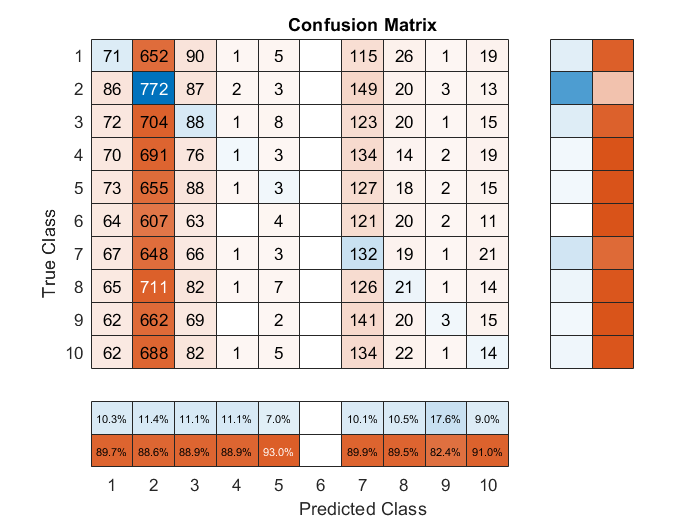

figure(3)
Confusion_Chart = confusionchart(conf_Matrix, cls, ...
    "Title", "Confusion Matrix", ...
    "ColumnSummary","column-normalized", ...
    "RowSummary","row-normalized");

Next we're calculating accuracy. It is equal to the division of the all successful predict number to the all predict number

accuracy = sum(double(YTest(:)) == yPredTest,'all')/numel(yPredTest) * 100

accuracy = 11.0500

**Let's test the second train - 30,000**

yPredTest2 = trainedModel_30000.predictFcn(xtestreshaped(1:10000, :));
yPredTest2(10:20)

ans =      2
     2
     2
     2
     2
     2
     2
     2
     3
     3


YTest(10:20)

ans = 11×1 categorical array
     9 
     0 
     6 
     9 
     0 
     1 
     5 
     9 
     7 
     3 
     4 


[conf_Matrix2, cls2] = confusionmat(double(YTest(:)),yPredTest2(:))

conf_Matrix2 =     15   527   123    72     1    23    13   129    67    10
    18   623   132   104     1    19    19   125    74    20
     9   546   119    86     0    22    16   160    65     9
    11   568   101    93     0    12    13   129    71    12
     9   558    96    78     0    15    13   123    78    12
     3   498    93    67     0    19    13   118    66    15
    11   517   109    77     0     8    14   144    68    10
     7   561   108    91     1    27     9   140    70    14
     8   527   118    76     0    15    17   136    64    13
    10   545   106    99     1    28    15   135    64     6


cls2 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


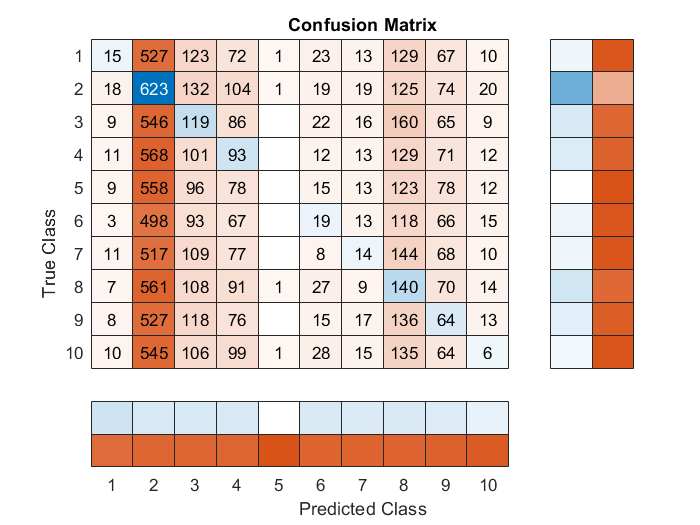

figure(4)
Confusion_Chart = confusionchart(conf_Matrix2, cls2, ...
    "Title", "Confusion Matrix", ...
    "ColumnSummary","column-normalized", ...
    "RowSummary","row-normalized");

Next we're calculating accuracy. It is equal to the division of the all successful predict number to the all predict number

accuracy2 = sum(double(YTest(:)) == yPredTest2,'all')/numel(yPredTest2)

accuracy2 = 0.1093

**Let's test the second train - 30,000 - Linear Discriminant**

yPredTest3 = trainedModel_LiDis_30000.predictFcn(xtestreshaped(1:10000, :));
yPredTest3(10:20)

ans =      4
    10
    10
     3
     3
     3
     7
     6
     3
     3


YTest(10:20)

ans = 11×1 categorical array
     9 
     0 
     6 
     9 
     0 
     1 
     5 
     9 
     7 
     3 
     4 


[conf_Matrix3, cls3] = confusionmat(double(YTest(:)),yPredTest3(:))

conf_Matrix3 =     93   113   123   127    71    52   106    90   104   101
   105   126   133   151    95    63   116   105   133   108
    83   120   115   131    87    72   126   107   101    90
    73   113   116   118    88    64   120    99   108   111
    87   116   112   110    72    64   104   105   101   111
    82    93   117   105    82    43   100    72    98   100
    77   119   107   106    86    59   106    91   101   106
   104   115   111   100    85    62   143   106    98   104
    93   114   120   112    87    56    90   103   104    95
    75   116   115   113    88    56   112    98   121   115


cls3 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


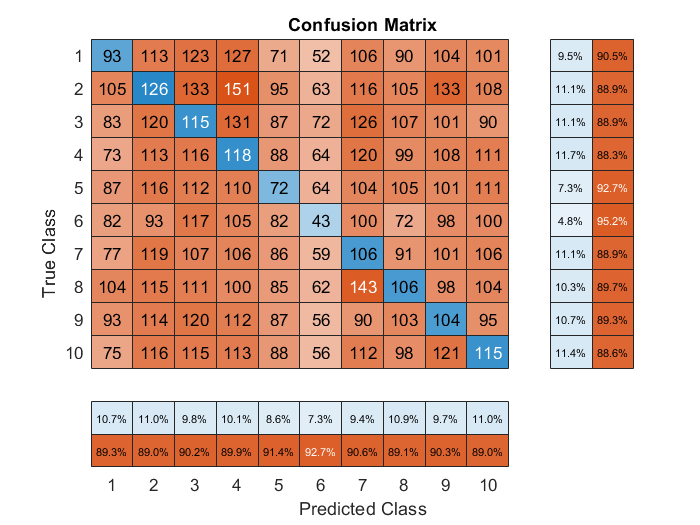

figure(5)
Confusion_Chart = confusionchart(conf_Matrix3, cls3, ...
    "Title", "Confusion Matrix", ...
    "ColumnSummary","column-normalized", ...
    "RowSummary","row-normalized");

Next we're calculating accuracy. It is equal to the division of the all successful predict number to the all predict number

accuracy3 = sum(double(YTest(:)) == yPredTest3,'all')/numel(yPredTest3)

accuracy3 = 0.0998